# Assembling time series correlation plots

  
clear
fs=96; 
load('trimmed_resultsNO20.mat'); % trimmed poavg to full sampling days

poavg_all = {Indra_1_poavg Indra_2_poavg Indra_3_poavg Indra_4_poavg Indra_5_poavg Indra_6_poavg...
    JJTug_1_poavg JJTug_2_poavg JJTug_3_poavg JJTug_4_poavg JJTug_5_poavg JJTug_6_poavg};
edt={Indra_1_edt Indra_2_edt Indra_3_edt Indra_4_edt Indra_5_edt Indra_6_edt...
    JJTug_1_edt JJTug_2_edt JJTug_3_edt JJTug_4_edt JJTug_5_edt JJTug_6_edt}; 
hrmn_edt = {hrmn_edtI1 hrmn_edtI2 hrmn_edtI3 hrmn_edtI4 hrmn_edtI5 hrmn_edtI6...
    hrmn_edtJ1 hrmn_edtJ2 hrmn_edtJ3 hrmn_edtJ4 hrmn_edtJ5 hrmn_edtJ6};
    
tday={};
for i=1:length(edt) 
a = edt{i};
t=a-floor(a(1));  
tday=[tday,t];   % I SUSPECT THESE ARE UTC TIMES. 
end

%% Confirm frequency bands
low = find(freqlist >=150 & freqlist <=2000);
high = find(freqlist >=7000 & freqlist <=15000);

timeseries_low ={};
for i = 1:length(poavg_all)
    a = poavg_all{i};
    b = sum(a(low,:));
    timeseries_low = [timeseries_low, b];
    clear a b;
end

timeseries_high ={};
for i = 1:length(poavg_all)
    a = poavg_all{i};
    b = sum(a(high,:));
    timeseries_high = [timeseries_high, b];
    clear a b;
end

Make dusk box limits

% load suncycle
load("succession_suncycle.mat");


## Low Frequency

Put together a 3 panel figure

Left: timeseries, center histogram, right correlation scatter plot

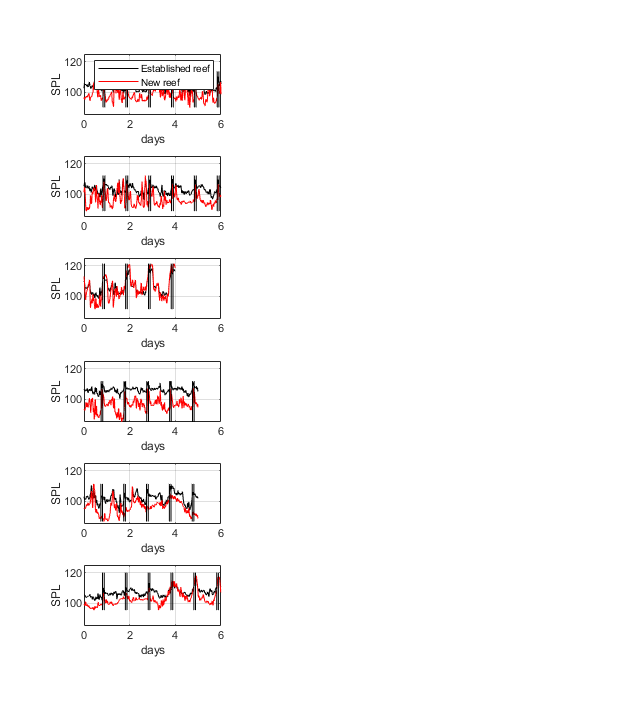

 
% timeseries
sm=1; 
figure; set(gcf,'units','centimeters','position',[0,0,17,19]);
subplot(6,3,1); 
%subplot(6,1,1); 
i=1; t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d1_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d1_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r');
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r');  end
ylim([85,125]); xlim([0,6]); grid on;  ylabel('SPL'); xlabel('days'); 
legend({'Established reef', 'New reef'});

%subplot(6,1,2); 
subplot(6,3,4); 
i=2;t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d2_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d2_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r'); 
     vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r'); end 
ylim([85,125]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days');   

%subplot(6,1,3); 
subplot(6,3,7); 
i=3; t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d3_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d3_dusk));
 if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r');
      vline(xvalue1,'k-'); vline(xvalue2, 'k-');
 else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r'); end 
ylim([85,125]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); 
 
%subplot(6,1,4); 
subplot(6,3,10); 
i=4; t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d4_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d4_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r');
     vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r');end 
ylim([85,125]); xlim([0,6]); grid on;ylabel('SPL'); xlabel('days');   

%subplot(6,1,5); 
subplot(6,3,13); 
i=5;t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d5_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d5_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r'); 
     vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r'); end 
ylim([85,125]); xlim([0,6]); grid on;  ylabel('SPL'); xlabel('days'); 

%subplot(6,1,6); 
subplot(6,3,16); 
i=6; t1=1/fs*(0:1:length(timeseries_low{i})-1);  t2=1/fs*(0:1:length(timeseries_low{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d6_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d6_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_low{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_low{i+6}),3),'r')
     vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_low{i})); hold on; plot(t2,10*log10(timeseries_low{i+6}),'r'); end 
ylim([85,125]); xlim([0,6]); grid on; xlabel('days'); ylabel('SPL'); xlabel('days'); 


%print(gcf,'test_timeseries.eps','-depsc',  )


 Histograms

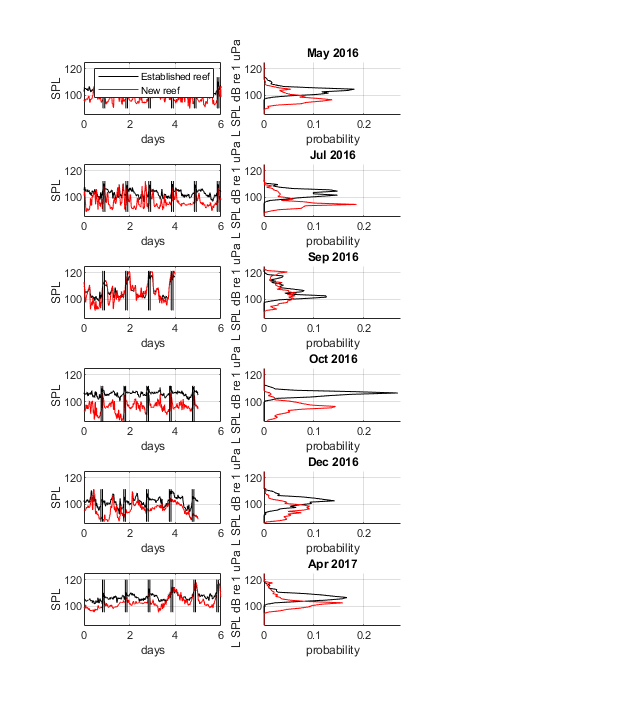

 
% histgram
bins=85:1:125;  
binscnt=(diff(bins(1:2)))/2+bins(1:end-1); 
subplot(6,3,2);
%subplot(6,1,1);
i=1; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); % ylabel('L SPL dB re 1 uPa'); title('May 2016')
    
subplot(6,3,5);
%subplot(6,1,2);
i=2; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); %ylabel('L SPL dB re 1 uPa'); title('Jul 2016')

subplot(6,3,8);
%subplot(6,1,3);
i=3; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); % ylabel('L SPL dB re 1 uPa'); title('Sep 2016')
    
subplot(6,3,11);
%subplot(6,1,4);
i=4;if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); % ylabel('L SPL dB re 1 uPa'); title('Oct 2016')
     
subplot(6,3,14);
%subplot(6,1,5);
i=5;if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); %ylabel('L SPL dB re 1 uPa'); title('Dec 2016')
    
subplot(6,3,17);
%subplot(6,1,5);
 i=6; if sm==1; cc1=histcounts(smooth(10*log10(timeseries_low{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_low{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_low{i}),bins); cc2=histcounts(10*log10(timeseries_low{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([85,125]) 
    grid on; yticklabels([]); %ylabel('L SPL dB re 1 uPa'); title('Apr 2017')

Correlation

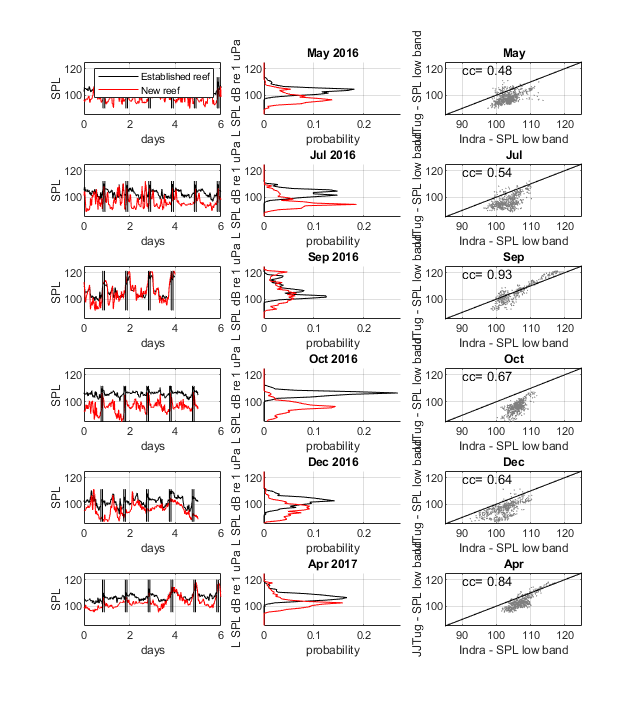

% correlation % not pearson correlation, but covariance of A and B
subplot(6,3,3); 
%subplot(6,1,1);
i=1;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','MarkerSize', 3, "Color",[0.5 0.5 0.5]); hold on; %   <-- needed for plot() not for scatter()
%     'MarkerFaceColor',[0.3 0.3 0.3],...
%     'MarkerEdgeColor', [0.5 0.5 0.5], ...
%     'LineWidth', 0.1); alpha(0.3); hold on; 
xlim([85,125]); ylim([85,125]); grid on;xlabel('Established Reef SPL'); ylabel('New Reef SPL'); 
%title('May'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])  
%legend('Indra vs. JJTug', 'one-to-one line')

subplot(6,3,6);
%subplot(6,1,2);
i=2;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([85,125]); ylim([85,125]); grid on;  xlabel('Established Reef SPL'); ylabel('New Reef SPL');  
%title('Jul'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,9); 
%subplot(6,1,3);
i=3;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([85,125]); ylim([85,125]); grid on; xlabel('Established Reef SPL'); ylabel('New Reef SPL');  
%title('Sep'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])


subplot(6,3,12); 
%subplot(6,1,4);
i=4;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([85,125]); ylim([85,125]);grid on;  xlabel('Established Reef SPL'); ylabel('New Reef SPL');  
%title('Oct'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,15); 
%subplot(6,1,5);
i=5;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([85,125]); ylim([85,125]); grid on; xlabel('Established Reef SPL'); ylabel('New Reef SPL'); 
%title('Dec'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,18); 
%subplot(6,1,6);
i=6;plot(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([85,125]); ylim([85,125]); grid on; xlabel('Established Reef SPL'); ylabel('New Reef SPL'); 
%title('Apr'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_low{i}),3),smooth(10*log10(timeseries_low{i+6}),3)); 
text(90,120,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

## High Frequency

% Timeseries
sm=1; 
figure; set(gcf,'units','centimeters','position',[0,0,17,19]); 
subplot(6,3,1); 
i=1; t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d1_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d1_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r'); 
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r');  end
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); 
%legend({'Indra 3-pt mv. avg.', 'JJTug 3-pt mv. avg.'});  title('May');

subplot(6,3,4); 
i=2;t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d2_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d2_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r'); 
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r'); end 
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); % title('Jul');

subplot(6,3,7); 
i=3; t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d3_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d3_dusk));
 if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r');
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
 else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r'); end 
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); % title('Sep');

subplot(6,3,10); 
i=4; t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d4_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d4_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r');
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r');end 
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); %title('Oct');  

subplot(6,3,13); 
i=5;t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d5_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d5_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r'); 
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r'); end 
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); %title('Dec'); 

subplot(6,3,16); 
i=6; t1=1/fs*(0:1:length(timeseries_high{i})-1);  t2=1/fs*(0:1:length(timeseries_high{i+6})-1); 
xvalue1 = t1(find(hrmn_edt{i} == d6_sSET-0.25)); xvalue2 = t1(find(hrmn_edt{i} == d6_dusk));
if sm==1; plot(t1,smooth(10*log10(timeseries_high{i}),3),'k'); hold on; plot(t2,smooth(10*log10(timeseries_high{i+6}),3),'r')
    vline(xvalue1,'k-'); vline(xvalue2, 'k-');
else; plot(t1,10*log10(timeseries_high{i})); hold on; plot(t2,10*log10(timeseries_high{i+6}),'r'); end 
ylim([95,130]); xlim([0,6]); grid on; ylabel('SPL'); xlabel('days'); %title('Apr') ;


% Histograms
sm=1; 
bins=90:1:130;  
binscnt=(diff(bins(1:2)))/2+bins(1:end-1); 
subplot(6,3,2); 
i=1; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt,'k'); plot(cc2/sum(cc2),binscnt,'r'); xlim([0,0.275]); xlabel('probability');  ylim([95,130])  
    grid on; yticklabels([]); %ylabel('H SPL dB re 1 uPa'); title('May 2016')
     %legend({'Indra', 'JJTug'})

subplot(6,3,5); 
i=2; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt, 'k'); plot(cc2/sum(cc2), binscnt, 'r');xlim([0,0.275]); xlabel('probability'); ylim([95,130])  
    grid on; yticklabels([]);% ylabel('H SPL dB re 1 uPa'); title('Jul 2016')

subplot(6,3,8); 
i=3; 
if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt, 'k'); plot(cc2/sum(cc2),binscnt, 'r');xlim([0,0.275]); xlabel('probability'); ylim([95,130]) 
    grid on; yticklabels([]);%ylabel('H SPL dB re 1 uPa'); grid on; title('Sep 2016')
    
subplot(6,3,11); 
i=4;if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
    hold on; plot(cc1/sum(cc1),binscnt, 'k'); plot(cc2/sum(cc2),binscnt, 'r');xlim([0,0.275]); xlabel('probability'); ylim([95,130]) 
    grid on; yticklabels([]);% ylabel('H SPL dB re 1 uPa'); grid on; title('Oct 2016')

subplot(6,3,14); 
 i=5;if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
   hold on; plot(cc1/sum(cc1),binscnt, 'k'); plot(cc2/sum(cc2),binscnt, 'r');xlim([0,0.275]); xlabel('probability'); ylim([95,130])  
    grid on; yticklabels([]);% ylabel('H SPL dB re 1 uPa'); grid on; title('Dec 2016')
    
subplot(6,3,17); 
 i=6; if sm==1; cc1=histcounts(smooth(10*log10(timeseries_high{i}),3),bins); cc2=histcounts(smooth(10*log10(timeseries_high{i+6}),3),bins); 
else; cc1=histcounts(10*log10(timeseries_high{i}),bins); cc2=histcounts(10*log10(timeseries_high{i+6}),bins);end 
   hold on; plot(cc1/sum(cc1),binscnt, 'k'); plot(cc2/sum(cc2),binscnt, 'r');xlim([0,0.275]); xlabel('probability'); ylim([95,130]) 
   grid on; yticklabels([]);% ylabel('H SPL dB re 1 uPa'); grid on; title('Apr 2017')
    
    
% Correlation

subplot(6,3,3); 
i=1;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]);  ylim([95,115]); grid on; xlabel('Established reef SPL'); ylabel('New Reef SPL'); 
%title('May'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])  
%legend('Indra vs. JJTug', 'one-to-one line')

subplot(6,3,6); 
i=2;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]);  ylim([95,115]); grid on;  xlabel('Established reef SPL'); ylabel('New Reef SPL');  
%title('Jul');
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,9); 
i=3;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]);  ylim([95,115]); grid on; xlabel('Established reef SPL'); ylabel('New Reef SPL'); 
%title('Sep'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])


subplot(6,3,12); 
i=4;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]);  ylim([95,115]);grid on; xlabel('Established reef SPL'); ylabel('New Reef SPL'); 
%title('Oct'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,15); 
i=5;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]); ylim([95,115]); grid on; xlabel('Established reef SPL'); ylabel('New Reef SPL'); 
%title('Dec'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])

subplot(6,3,18); 
i=6;plot(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3),'.','Color',[0.5 0.5 0.5],'MarkerSize', 3); hold on; 
xlim([110,130]);  ylim([95,115]); grid on; xlabel('Established reef SPL'); ylabel('New Reef SPL'); 
%title('Apr'); 
plot([85,125],[85,125],'k'); 
cc=corrcoef(smooth(10*log10(timeseries_high{i}),3),smooth(10*log10(timeseries_high{i+6}),3)); 
text(125,98,['cc= '  sprintf('%0.2f%',cc(1,2)) ])
